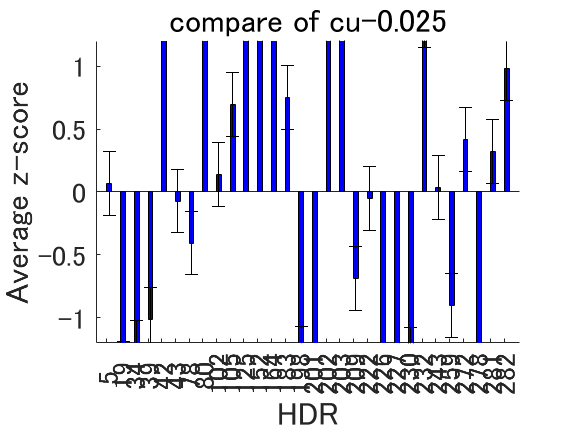

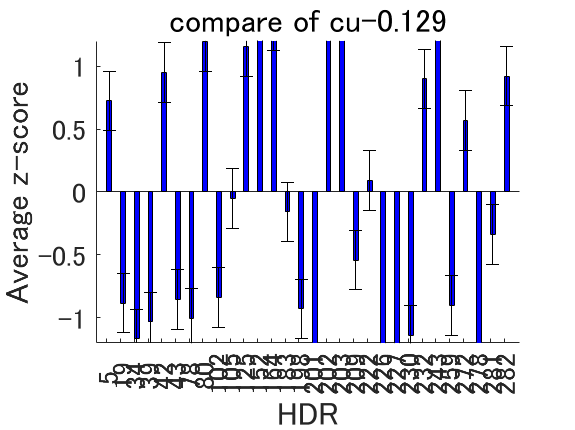

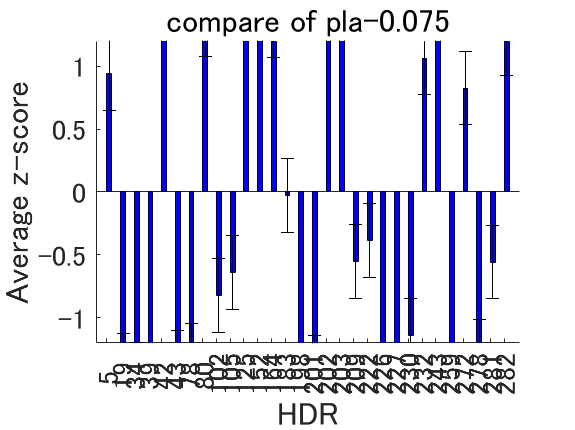

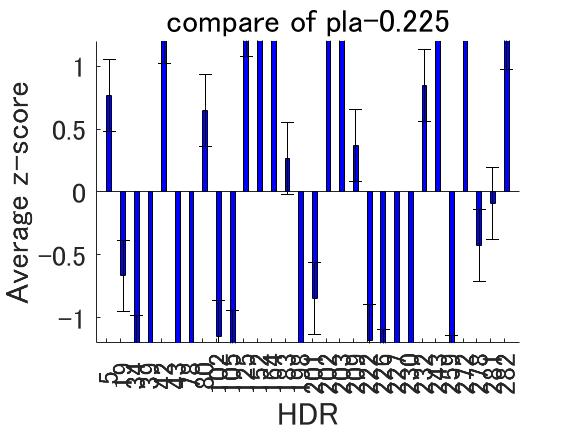

%% 1. 実験条件・照明環境ごとの選好尺度値（被験者平均）
% activate at ' exp3_analysis '
%-----------------Initialization------------------
clear all;
load('./inouedata/reshaped/z_psvList.mat')

load('./inouedata/reshaped/z_conditionList.mat')
condition_exp2 = experiment_condition;

ana_result = "analysis/";
colNames = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
%-----------------Setting------------------
searchColumn = [1,3];
%-----------------Analyze------------------
groupColumns = condition_exp2(:, searchColumn);

columnCells = num2cell(groupColumns, 1);
[groupIdx, uniqueGroups1,uniqueGroups2] = findgroups(columnCells{:});

groupMeans = splitapply(@(x) mean(x, 1), psv_experiment2, groupIdx);

name = strcat(uniqueGroups1,'-', uniqueGroups2);

error_exp3 = std(groupMeans, 0, 2)/ sqrt(size(groupMeans, 2));
error_exp3 = repmat(error_exp3, 1, 30);
for row = 1:size(groupMeans,1)
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, groupMeans(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    h3 = errorbar(x + bar_width/2, groupMeans(row, :), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' name{row}], 'FontSize', 16);

    plotname = strcat(ana_result, '/I_', name{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

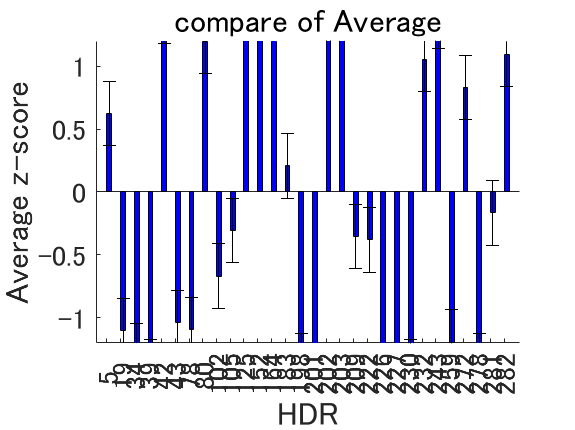


% Av graph
AvgroupsMeans = mean(groupMeans, 1);
error_av = std(AvgroupsMeans, 0, 2)/ sqrt(size(AvgroupsMeans, 2));
error_av = repmat(error_av, 1, 30);

figure;
hold on;
bar_width = 0.35;
x = 1:length(colNames);
avb = bar(x + bar_width/2, AvgroupsMeans, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh = errorbar(x + bar_width/2, AvgroupsMeans, error_av, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(colNames));
set(gca, 'XTickLabel', colNames, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Average z-score', 'FontSize', 16);
title('compare of Average', 'FontSize', 16);
plotname = strcat(ana_result, '/I_Average.jpg');
saveas(gcf, plotname);
hold off;